clear all

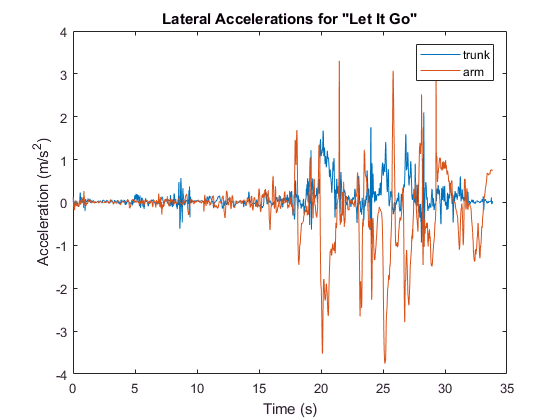

load letitbetrunk.mat
load letitbearm.mat

Fs = 100;
startcut = 200;
t_lib = linspace(0,length(letitbetrunk(325+startcut:end,1))/Fs,length(letitbetrunk(325+startcut:end,1)));
plot(t_lib,letitbetrunk(325+startcut:end, 7)) %starting from sample 800, cutting off at end of trunk
hold on
plot(t_lib,letitbearm(327+startcut:length(letitbetrunk)-(325-327),7))
legend('trunk', 'arm')
title('Lateral Accelerations for "Let It Go"')
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')
hold off

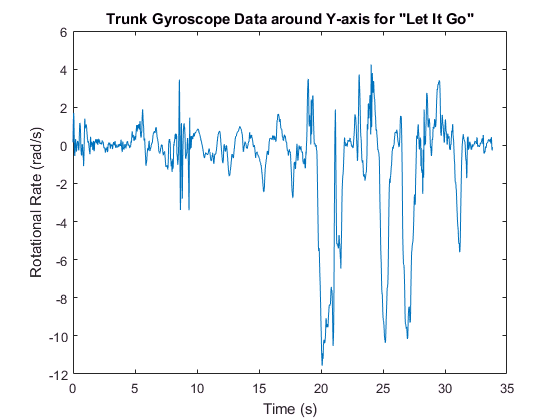

plot(t_lib,letitbetrunk(325+startcut:end,2))
title('Trunk Gyroscope Data around Y-axis for "Let It Go"')
xlabel('Time (s)')
ylabel('Rotational Rate (rad/s)')

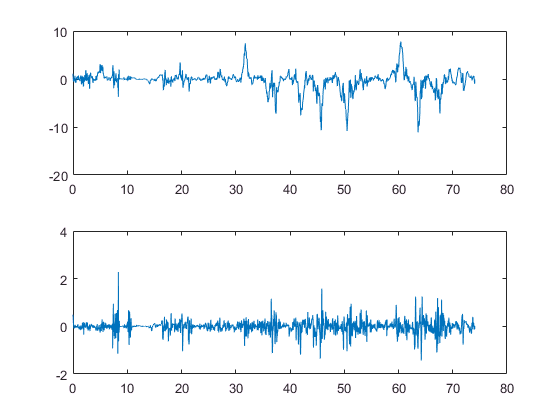

load photographarm.mat
load photographtrunk.mat

startcut = 0;
t_p = linspace(0,length(photographarm(477+startcut:end,1))/Fs,length(photographarm(477+startcut:end,1)));

figure
subplot(2,1,1)
plot(t_p,photographtrunk(480+startcut:length(photographarm)+3,2))
subplot(2,1,2)
plot(t_p,photographtrunk(480+startcut:length(photographarm)+3,6))

figure
subplot(2,1,1)
plot(t_p,photographarm(477+startcut:end,2))
subplot(2,1,2)
plot(t_p,photographarm(477+startcut:end,6))
title('photograph gyro')

[fg_libt, freqg_libt, bpmg_libt] = findbpmrange('letitbetrunk.mat', Fs, 'gyro', 'y', 525, 3907)

fg_libt =   -49.9852  -49.9557  -49.9261  -49.8965  -49.8670  -49.8374  -49.8079  -49.7783  -49.7487  -49.7192  -49.6896  -49.6601  -49.6305  -49.6009  -49.5714  -49.5418  -49.5123  -49.4827  -49.4531  -49.4236  -49.3940  -49.3645  -49.3349  -49.3054  -49.2758  -49.2462  -49.2167  -49.1871  -49.1576  -49.1280  -49.0984  -49.0689  -49.0393  -49.0098  -48.9802  -48.9506  -48.9211  -48.8915  -48.8620  -48.8324  -48.8028  -48.7733  -48.7437  -48.7142  -48.6846  -48.6550  -48.6255  -48.5959  -48.5664  -48.5368


freqg_libt =     0.5510
    0.8455
    1.6387
    0.3405
    0.9751
    0.9917
    1.1691
    0.6705
    0.5189
    1.5037


bpmg_libt =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


plot(fg_libt, freqg_libt)
title('let it be trunk gyro frequency')
[f_libt, freq_libt, phase_libt, bpm_libt] = findbpmrange('letitbetrunk.mat',Fs,'accel','y',525,3907)

f_libt =   -49.9852  -49.9557  -49.9261  -49.8965  -49.8670  -49.8374  -49.8079  -49.7783  -49.7487  -49.7192  -49.6896  -49.6601  -49.6305  -49.6009  -49.5714  -49.5418  -49.5123  -49.4827  -49.4531  -49.4236  -49.3940  -49.3645  -49.3349  -49.3054  -49.2758  -49.2462  -49.2167  -49.1871  -49.1576  -49.1280  -49.0984  -49.0689  -49.0393  -49.0098  -48.9802  -48.9506  -48.9211  -48.8915  -48.8620  -48.8324  -48.8028  -48.7733  -48.7437  -48.7142  -48.6846  -48.6550  -48.6255  -48.5959  -48.5664  -48.5368


freq_libt =     1.1994
    1.0450
    1.1149
    1.1983
    1.0958
    1.2187
    1.0401
    1.0438
    1.3159
    1.1399


phase_libt =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


bpm_libt = 76.2637

plot(f_libt, phase_libt)
[f_libt, freq_libt, phase_libt, bpm_libt] = findbpmrange('letitbetrunk.mat',Fs,'accel','x',525,3907)

f_libt =   -49.9852  -49.9557  -49.9261  -49.8965  -49.8670  -49.8374  -49.8079  -49.7783  -49.7487  -49.7192  -49.6896  -49.6601  -49.6305  -49.6009  -49.5714  -49.5418  -49.5123  -49.4827  -49.4531  -49.4236  -49.3940  -49.3645  -49.3349  -49.3054  -49.2758  -49.2462  -49.2167  -49.1871  -49.1576  -49.1280  -49.0984  -49.0689  -49.0393  -49.0098  -48.9802  -48.9506  -48.9211  -48.8915  -48.8620  -48.8324  -48.8028  -48.7733  -48.7437  -48.7142  -48.6846  -48.6550  -48.6255  -48.5959  -48.5664  -48.5368


freq_libt =     1.5068
    1.0184
    1.4788
    1.4481
    0.9963
    1.3624
    1.2053
    0.8077
    1.3839
    1.2672


phase_libt =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


bpm_libt = 120.6030

[f_libt, freq_libt, bpm_libt] = findbpmrange('letitbetrunk.mat',Fs,'accel','z',525,3907)

f_libt =   -49.9852  -49.9557  -49.9261  -49.8965  -49.8670  -49.8374  -49.8079  -49.7783  -49.7487  -49.7192  -49.6896  -49.6601  -49.6305  -49.6009  -49.5714  -49.5418  -49.5123  -49.4827  -49.4531  -49.4236  -49.3940  -49.3645  -49.3349  -49.3054  -49.2758  -49.2462  -49.2167  -49.1871  -49.1576  -49.1280  -49.0984  -49.0689  -49.0393  -49.0098  -48.9802  -48.9506  -48.9211  -48.8915  -48.8620  -48.8324  -48.8028  -48.7733  -48.7437  -48.7142  -48.6846  -48.6550  -48.6255  -48.5959  -48.5664  -48.5368


freq_libt =     0.7419
    0.9735
    1.1216
    0.7257
    0.6068
    0.9378
    1.1683
    0.6460
    0.4919
    0.9308


bpm_libt =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


plot(f_libt,freq_libt)
[f_liba, freq_liba, bpm_liba] = findbpmrange('letitbearm.mat',Fs,'accel','y',527,length(letitbetrunk))

f_liba =   -49.9852  -49.9556  -49.9261  -49.8965  -49.8669  -49.8373  -49.8077  -49.7782  -49.7486  -49.7190  -49.6894  -49.6599  -49.6303  -49.6007  -49.5711  -49.5416  -49.5120  -49.4824  -49.4528  -49.4232  -49.3937  -49.3641  -49.3345  -49.3049  -49.2754  -49.2458  -49.2162  -49.1866  -49.1571  -49.1275  -49.0979  -49.0683  -49.0387  -49.0092  -48.9796  -48.9500  -48.9204  -48.8909  -48.8613  -48.8317  -48.8021  -48.7726  -48.7430  -48.7134  -48.6838  -48.6542  -48.6247  -48.5951  -48.5655  -48.5359


freq_liba =     0.2003
    0.5470
    0.5605
    0.5080
    0.4399
    0.7782
    1.1644
    1.5100
    1.4719
    1.5518


bpm_liba =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


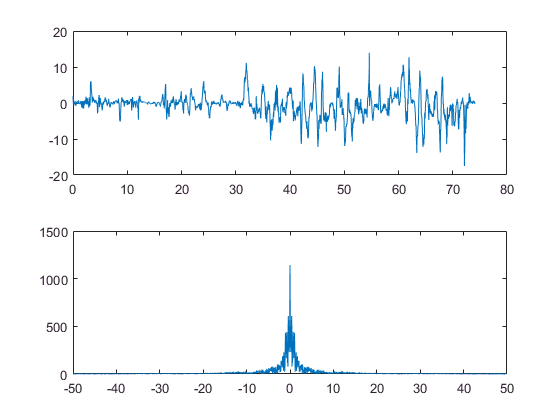

plot(f_liba,freq_liba)

load architectofthemindtrunk.mat
load architectofthemindarm.mat

startcut = 50;
plot(architectofthemindtrunk(611+startcut:end, 7))
hold on
plot(architectofthemindarm(542+startcut:length(architectofthemindtrunk)-(611-542), 7))
hold off
[f_aotmt, freq_aotmt, bpm_aotmt] = findbpmrange('architectofthemindtrunk.mat',Fs,'accel','y',611,length(architectofthemindtrunk))

f_aotmt =   -49.9886  -49.9658  -49.9430  -49.9203  -49.8975  -49.8747  -49.8519  -49.8291  -49.8063  -49.7835  -49.7608  -49.7380  -49.7152  -49.6924  -49.6696  -49.6468  -49.6241  -49.6013  -49.5785  -49.5557  -49.5329  -49.5101  -49.4874  -49.4646  -49.4418  -49.4190  -49.3962  -49.3734  -49.3506  -49.3279  -49.3051  -49.2823  -49.2595  -49.2367  -49.2139  -49.1912  -49.1684  -49.1456  -49.1228  -49.1000  -49.0772  -49.0545  -49.0317  -49.0089  -48.9861  -48.9633  -48.9405  -48.9177  -48.8950  -48.8722


freq_aotmt =     0.6829
    1.3418
    1.0373
    0.8471
    1.1497
    0.6870
    0.4657
    1.1052
    0.7119
    0.3938


bpm_aotmt =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


plot(f_aotmt,freq_aotmt)
[f_aotma, freq_aotma, bpm_aotma] = findbpmrange('architectofthemindarm.mat',Fs,'accel','y',542,length(architectofthemindtrunk)-(611-542))

f_aotma =   -49.9886  -49.9658  -49.9430  -49.9203  -49.8975  -49.8747  -49.8519  -49.8291  -49.8063  -49.7835  -49.7608  -49.7380  -49.7152  -49.6924  -49.6696  -49.6468  -49.6241  -49.6013  -49.5785  -49.5557  -49.5329  -49.5101  -49.4874  -49.4646  -49.4418  -49.4190  -49.3962  -49.3734  -49.3506  -49.3279  -49.3051  -49.2823  -49.2595  -49.2367  -49.2139  -49.1912  -49.1684  -49.1456  -49.1228  -49.1000  -49.0772  -49.0545  -49.0317  -49.0089  -48.9861  -48.9633  -48.9405  -48.9177  -48.8950  -48.8722


freq_aotma =     0.8222
    0.5139
    0.4557
    0.6047
    0.3969
    0.3765
    0.6687
    0.8752
    0.7678
    0.6717


bpm_aotma =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


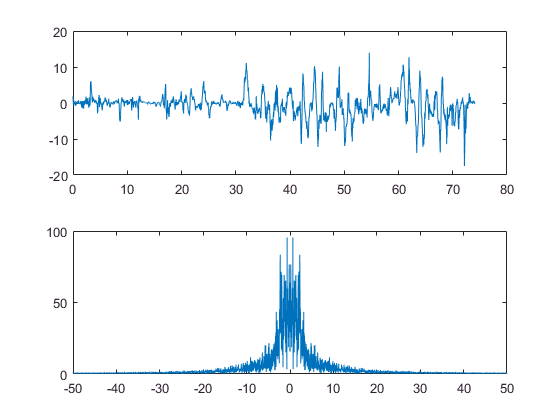

plot(f_aotma,freq_aotma)

load photographtrunk.mat
load photographarm.mat

plot(photographtrunk(461:length(photographarm)+1,5))
hold on
plot(photographarm(460:end,5))
hold off
legend('trunk','arm')
[f_pt, mag_pt, bpm_pt] = findbpmrange('photographtrunk.mat',Fs,'accel','y',461,length(photographarm)+1)

f_pt =   -49.9933  -49.9798  -49.9663  -49.9528  -49.9394  -49.9259  -49.9124  -49.8990  -49.8855  -49.8720  -49.8585  -49.8451  -49.8316  -49.8181  -49.8047  -49.7912  -49.7777  -49.7642  -49.7508  -49.7373  -49.7238  -49.7104  -49.6969  -49.6834  -49.6699  -49.6565  -49.6430  -49.6295  -49.6161  -49.6026  -49.5891  -49.5756  -49.5622  -49.5487  -49.5352  -49.5218  -49.5083  -49.4948  -49.4813  -49.4679  -49.4544  -49.4409  -49.4275  -49.4140  -49.4005  -49.3870  -49.3736  -49.3601  -49.3466  -49.3332


mag_pt =     1.2534
    1.0017
    0.8492
    0.7269
    0.4136
    0.0966
    0.2496
    0.4796
    0.6596
    1.0139


bpm_pt =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


plot(f_pt,mag_pt)
[f_pa, mag_pa, bpm_pa] = findbpmrange('photographarm.mat',Fs,'accel','y',460,length(photographarm))

f_pa =   -49.9933  -49.9798  -49.9663  -49.9528  -49.9394  -49.9259  -49.9124  -49.8990  -49.8855  -49.8720  -49.8585  -49.8451  -49.8316  -49.8181  -49.8047  -49.7912  -49.7777  -49.7642  -49.7508  -49.7373  -49.7238  -49.7104  -49.6969  -49.6834  -49.6699  -49.6565  -49.6430  -49.6295  -49.6161  -49.6026  -49.5891  -49.5756  -49.5622  -49.5487  -49.5352  -49.5218  -49.5083  -49.4948  -49.4813  -49.4679  -49.4544  -49.4409  -49.4275  -49.4140  -49.4005  -49.3870  -49.3736  -49.3601  -49.3466  -49.3332


mag_pa =     0.9652
    1.5265
    0.8511
    0.9856
    1.2308
    0.7435
    0.1520
    0.5335
    0.2016
    0.9809


bpm_pa =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


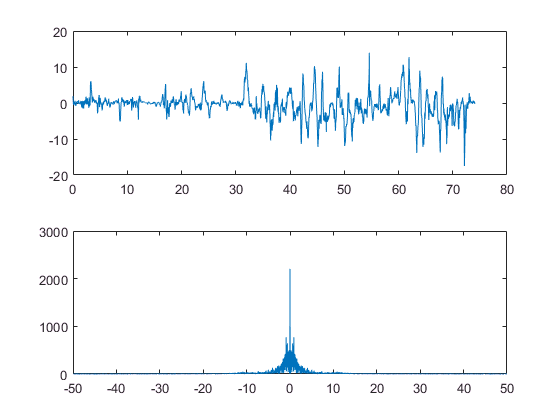

plot(f_pa,mag_pa)

function [f, mag, phase, bpm] = findbpmrange(filename, Fs, sensor, direction, start, final)
    file1 = cell2mat(struct2cell(load(filename)));
    file = file1(start:final,:);
    N = length(file(:,1));
    f = linspace(-Fs/2, Fs/2 - Fs/N, N) + Fs/(2*N)*mod(N,2);
    if strcmp(sensor,'accel')
        if strcmp(direction,'x')
            dir = 6;
        elseif strcmp(direction,'y')
            dir = 5;
        elseif strcmp(direction,'z')
            dir = 7;
        else
            dir = 5;
        end
    elseif strcmp(sensor,'gyro')
        if strcmp(direction,'x')
            dir = 3;
        elseif strcmp(direction,'y')
            dir = 2;
        elseif strcmp(direction,'z')
            dir = 4;
        else
            dir = 2;
        end
    end
    mag = fftshift(abs(fft(file(:,dir))));
    threshold = max(abs(fft(file(:,dir))))/10000; %tolerance threshold
    clean_phase = abs(fft(file(:,dir)));
    clean_phase(clean_phase < threshold) = 0;
    phase = angle(fftshift(clean_phase));
 
    positive = mag(f > 0.3);
    H = max(positive);
    bps = find(mag == H);
    bpm = abs(f(bps(1)))*60;
end